% Define the file name and open the file for reading
filename = 'ZeroCompData.txt';


% Read the LTSpice data as a table
data = readtable(filename, 'Delimiter', '\t'); % Assuming tab-delimited data

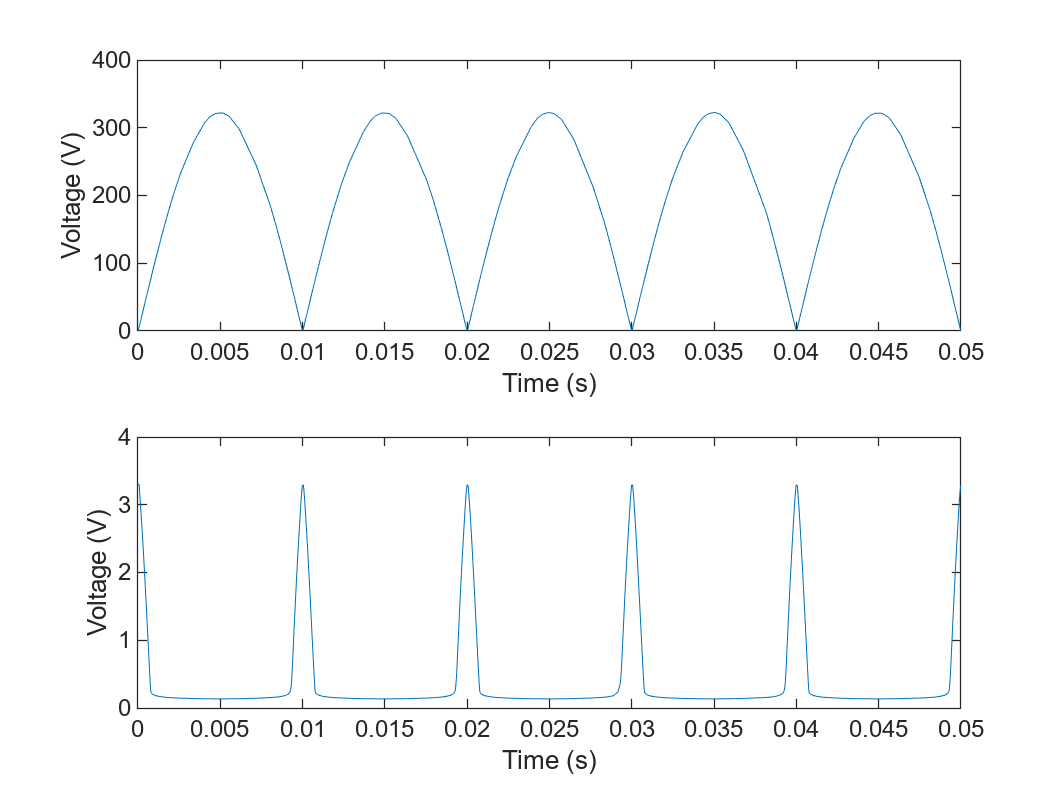

% Access the columns in the table by name
time = data.time;
FBR_Voltage = data.V_fbr_output_;
GPIO_Voltage = data.V_gpio_;

% Create a plot
figure;
subplot(2, 1, 1); % 2 rows, 1 column, first plot
plot(time, FBR_Voltage);
xlabel('Time (s)');
ylabel('Voltage (V)');

subplot(2, 1, 2);
plot(time,GPIO_Voltage);
xlabel('Time (s)');
ylabel('Voltage (V)');


saveas(gcf, 'plots/opto_output_and_input.png');

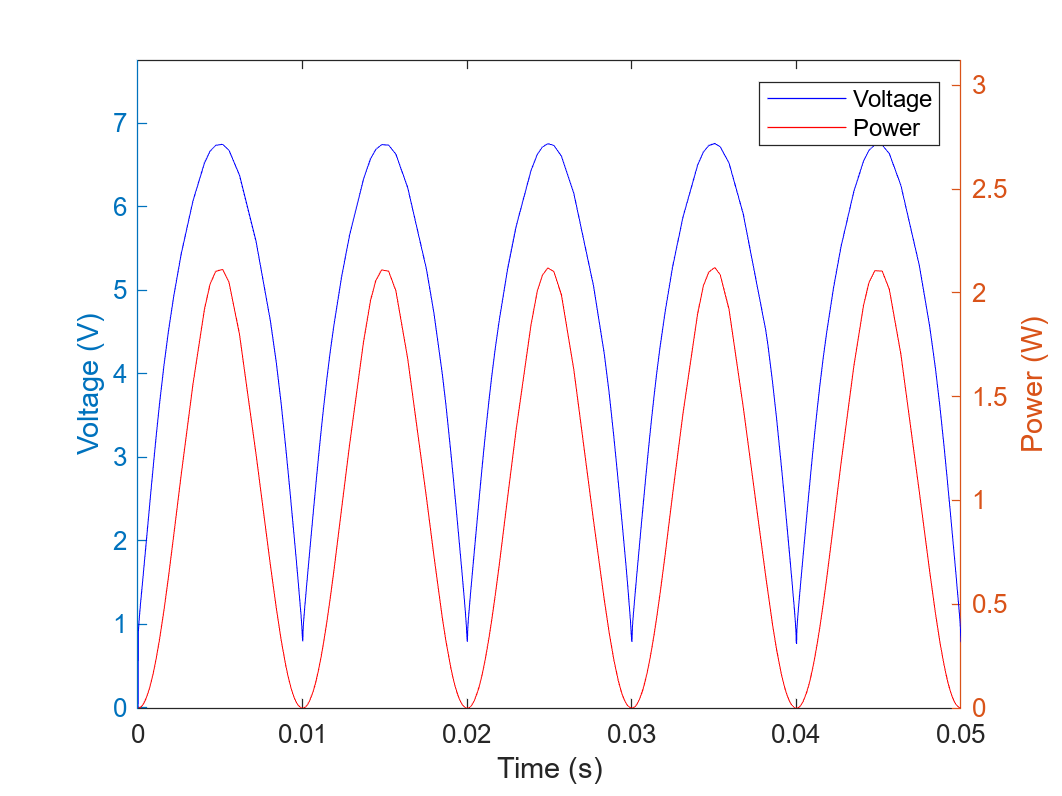

res_power = data.V_After_R1_FBR_Output__I_R1_;
v_after_r1 = data.V_after_r1_;
zener_current = data.I_D1_;
transistor_current = data.I_R2_;
power_resistor_current = data.I_R1_;
opto_input_current = data.I_R3_;

figure;
yyaxis left;
plot(time, v_after_r1, 'b'); % Blue solid line
ylabel('Voltage (V)');
ylim([min(v_after_r1) max(v_after_r1)+1]); % Set the y-axis limits for Voltage

hold on; % Hold the plot so that you can add more data

% Plot the Power data
yyaxis right;
plot(time, res_power, 'r'); % Red dashed line
ylabel('Power (W)');
ylim([min(res_power) max(res_power)+1]); % Set the y-axis limits for Power

% Add labels and title
xlabel('Time (s)');
legend('Voltage', 'Power');
hold off;

saveas(gcf, 'plots/res_sim.png');

max(res_power)

ans = 2.1225